% ChanSpecifier_methods_demo

## `ChanSpecifier` object construction with a folder path

clear;close all;clc;

dirpath = fileparts(which('WaveformChan.m'));

chanSpec = ChanSpecifier(dirpath)

chanSpec =   ChanSpecifier with properties:

                     List: [3x1 struct]
                 MatNames: {3x1 cell}
             MatNamesFull: {3x1 cell}
                ParentDir: {3x1 cell}
               ChanTitles: {3x1 cell}
            ChanTitlesAll: {15x1 cell}
    ChanTitlesMatNamesAll: {15x4 cell}
                   MatNum: 3
                  ChanNum: [3x1 double]


## Methods of `ChanSpecifier` object

methods(chanSpec)


Methods for class ChanSpecifier:

ChanSpecifier         
allind2matindchanind  
changepathplatform    
chantitles2chanind    
choose                
constructChan         
constructFileList     
constructRecord       
eq                    
getEventStats         
getPairsPerRecord     
getXG                 
getchanprop           
getstructNby1         
getstructOne          
gettable              
horzcat               
ischantitlematched    
ischanvalid           
ischanwithfield       
ismatnamematched      
ismatvalid            
matind2allind         
matindchanind2allind  
matnamesfull2matind   
saveobj               
vertcat               


Static methods:

loadobj               




## `ischanvalid`

`ischanvalid` and `ismatvalid` serve for a similar purpose; selecting subset of channels or mat files in a `ChanSpecifider` object. These two methods return `TF` logical vector that represent all the channels in the object. 

Calling `choose` method with `TF` as the input argument will construct a new ChanSpecifier object that contains only a subset of channels of your interest.

`[TF, names] = ischanvalid(chanSpec, chanpropname, func)`

`% chanpropname   filed name of channels`

`% func           function handle of a true-or-false function`

`% TF             logical vector for all the channels included in chanSpec`

`% names          the list of 'matfilename|chantitle' for all the channels`

You can see which channels are chosen in `TF` by executing: 

`names(TF)`

% Find channels whose |meanfiringrate| is higher than 0.8
[TF, names] = chanSpec.ischanvalid('meanfiringrate', @(x) x > 0.8)

TF =      0
     0
     0
     1
     0
     0
     0
     0
     1
     0
     0
     0
     0
     1
     0


names =     'kjx127a01@0-20_double.mat|onset'
    'kjx127a01@0-20_double.mat|LTS'
    'kjx127a01@0-20_double.mat|LTSmk'
    'kjx127a01@0-20_double.mat|probeA07e'
    'kjx127a01@0-20_double.mat|EEG'
    'kjx127a01@0-20_int16.mat|onset'
    'kjx127a01@0-20_int16.mat|LTS'
    'kjx127a01@0-20_int16.mat|LTSmk'
    'kjx127a01@0-20_int16.mat|probeA07e'
    'kjx127a01@0-20_int16.mat|EEG'
    'kjx127a01@0-20_single.mat|onset'
    'kjx127a01@0-20_single.mat|LTS'
    'kjx127a01@0-20_single.mat|LTSmk'
    'kjx127a01@0-20_single.mat|probeA07e'
    'kjx127a01@0-20_single.mat|EEG'


names(TF)

ans =     'kjx127a01@0-20_double.mat|probeA07e'
    'kjx127a01@0-20_int16.mat|probeA07e'
    'kjx127a01@0-20_single.mat|probeA07e'


In the following example, ismatched`any` returns true if `x` matches the regular expression expr

`TF = ismatchedany(str, expression)`

% Find channels whose |title| contains string |LTS|
[TF, names] = chanSpec.ischanvalid('title', @(x) ismatchedany(x, 'LTS'));
names(TF)

ans =     'kjx127a01@0-20_double.mat|LTS'
    'kjx127a01@0-20_double.mat|LTSmk'
    'kjx127a01@0-20_int16.mat|LTS'
    'kjx127a01@0-20_int16.mat|LTSmk'
    'kjx127a01@0-20_single.mat|LTS'
    'kjx127a01@0-20_single.mat|LTSmk'


## `ischantitlematched`

A wrapper of `ischanvalid`. Useful when you want to choose channels based on their chantitles with regular expression.

`[TF, names] = ischantitlematched(chanSpec, expr)`

`% expr        Regular expression in char type string or cell array of`

`%             strings.`

`%             String (char type). A field name of a channel structure`

`%             (chanSpec.List.channels.xxxxx) that is to be evaluated `

[TF, names] = chanSpec.ischantitlematched('LTS');

is equivalent to the following: 

[TF2, names] = chanSpec.ischanvalid('title', @(x) ismatchedany(x, 'LTS'));

isequal(TF, TF2)

ans =      1


## `ismatvalid`

Similar to `ischanvalid`, but works with mat files. The out put is channel basis+ the length of TF vector is equal to the sum of `chanSpec.ChanNum`

`[TF, names] = ismatvalid(chanSpec, matpropname, func)`

`% matpropname    a fieldname of chanSpec.List`

`% func           function handle of a true-or-false function`

`% TF             logical vector for all the channels included in chanSpec`

`% names          the list of 'matfilename|chantitle' for all the channels`

% Find channels whose parental mat files contain string 'double' in their
% |name| field.
[TF, names] = chanSpec.ismatvalid('name', @(x) ismatchedany(x, 'double'))

TF =      1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


names =     'kjx127a01@0-20_double.mat|onset'
    'kjx127a01@0-20_double.mat|LTS'
    'kjx127a01@0-20_double.mat|LTSmk'
    'kjx127a01@0-20_double.mat|probeA07e'
    'kjx127a01@0-20_double.mat|EEG'
    'kjx127a01@0-20_int16.mat|onset'
    'kjx127a01@0-20_int16.mat|LTS'
    'kjx127a01@0-20_int16.mat|LTSmk'
    'kjx127a01@0-20_int16.mat|probeA07e'
    'kjx127a01@0-20_int16.mat|EEG'
    'kjx127a01@0-20_single.mat|onset'
    'kjx127a01@0-20_single.mat|LTS'
    'kjx127a01@0-20_single.mat|LTSmk'
    'kjx127a01@0-20_single.mat|probeA07e'
    'kjx127a01@0-20_single.mat|EEG'


names(TF)

ans =     'kjx127a01@0-20_double.mat|onset'
    'kjx127a01@0-20_double.mat|LTS'
    'kjx127a01@0-20_double.mat|LTSmk'
    'kjx127a01@0-20_double.mat|probeA07e'
    'kjx127a01@0-20_double.mat|EEG'


Without an input argument, all channels will be selected.

TF  = chanSpec.ismatvalid;
all(TF)

ans =      1


You can use the TF output of `ismatvalid` or `ischanvalid` as the input argument of `ismatvalid` to select the parental `.mat` files.

% Find channles whose parental mat file exceeds 4000000 bytes.
TF = chanSpec.ismatvalid('bytes', @(x) x > 4000000);

TF2 = chanSpec.ismatvalid(TF)

TF2 =      1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


all(TF == TF2)

ans =      1


% Find channels whose |meanfiringrate| is higher than 0.8
[TF, names] = chanSpec.ischanvalid('meanfiringrate', @(x) x > 0.8);
names(TF)

ans =     'kjx127a01@0-20_double.mat|probeA07e'
    'kjx127a01@0-20_int16.mat|probeA07e'
    'kjx127a01@0-20_single.mat|probeA07e'



% Select all the channels contained in the parental mat files.
% In this particualr example, because all the mat files contain the same data, all the mat
% files will be chosen.
TF2 = chanSpec.ismatvalid(TF);
names(TF2)

ans =     'kjx127a01@0-20_double.mat|onset'
    'kjx127a01@0-20_double.mat|LTS'
    'kjx127a01@0-20_double.mat|LTSmk'
    'kjx127a01@0-20_double.mat|probeA07e'
    'kjx127a01@0-20_double.mat|EEG'
    'kjx127a01@0-20_int16.mat|onset'
    'kjx127a01@0-20_int16.mat|LTS'
    'kjx127a01@0-20_int16.mat|LTSmk'
    'kjx127a01@0-20_int16.mat|probeA07e'
    'kjx127a01@0-20_int16.mat|EEG'
    'kjx127a01@0-20_single.mat|onset'
    'kjx127a01@0-20_single.mat|LTS'
    'kjx127a01@0-20_single.mat|LTSmk'
    'kjx127a01@0-20_single.mat|probeA07e'
    'kjx127a01@0-20_single.mat|EEG'


## `ismatnamematched`

A wrapper of ismatvalid specialized for matching 'name' field with regular expression.

`[TF, names] = ismatnamematched(chanSpec, expr)`

[TF, names] = ismatnamematched(chanSpec, 'double')

TF =      1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


names =     'kjx127a01@0-20_double.mat|onset'
    'kjx127a01@0-20_double.mat|LTS'
    'kjx127a01@0-20_double.mat|LTSmk'
    'kjx127a01@0-20_double.mat|probeA07e'
    'kjx127a01@0-20_double.mat|EEG'
    'kjx127a01@0-20_int16.mat|onset'
    'kjx127a01@0-20_int16.mat|LTS'
    'kjx127a01@0-20_int16.mat|LTSmk'
    'kjx127a01@0-20_int16.mat|probeA07e'
    'kjx127a01@0-20_int16.mat|EEG'
    'kjx127a01@0-20_single.mat|onset'
    'kjx127a01@0-20_single.mat|LTS'
    'kjx127a01@0-20_single.mat|LTSmk'
    'kjx127a01@0-20_single.mat|probeA07e'
    'kjx127a01@0-20_single.mat|EEG'


is equivalent to the following:

[TF2, names] = chanSpec.ismatvalid('name', @(x) ismatchedany(x, 'double'))

TF2 =      1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


names =     'kjx127a01@0-20_double.mat|onset'
    'kjx127a01@0-20_double.mat|LTS'
    'kjx127a01@0-20_double.mat|LTSmk'
    'kjx127a01@0-20_double.mat|probeA07e'
    'kjx127a01@0-20_double.mat|EEG'
    'kjx127a01@0-20_int16.mat|onset'
    'kjx127a01@0-20_int16.mat|LTS'
    'kjx127a01@0-20_int16.mat|LTSmk'
    'kjx127a01@0-20_int16.mat|probeA07e'
    'kjx127a01@0-20_int16.mat|EEG'
    'kjx127a01@0-20_single.mat|onset'
    'kjx127a01@0-20_single.mat|LTS'
    'kjx127a01@0-20_single.mat|LTSmk'
    'kjx127a01@0-20_single.mat|probeA07e'
    'kjx127a01@0-20_single.mat|EEG'



isequal(TF, TF2)

ans =      1


## GUI option for `ismatvalid` and `ischanvalid`

GUI is also available.

`TF = chanSpec.ismatvalid('gui')`

`TF = chanSpec.ischanvalid('gui')`

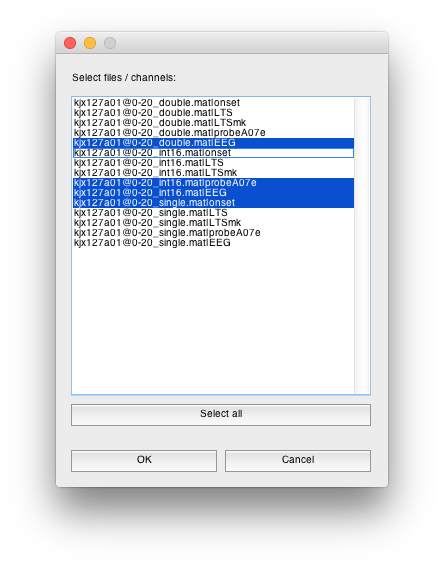

## `choose`

The mehtod `choose` is used in combination with `ismatvalid` and `ischanvalid`. Use the output `TF` of `ismatvalid` or `ischanvalid` as the input argument.

`[chanSpecout] = chanSpec.choose(TF) `

`% TF            logical column vector that is output of ismatvalid `

`%               or ischanvalid `

`%`

`% chanSpecout  New ChanSpecfier object that contains only .mat files`

`               and channels that are specified by the input TF`

% Find channels whose |meanfiringrate| is higher than 0.8
[TF, names] = chanSpec.ischanvalid('meanfiringrate', @(x) x > 0.8)

TF =      0
     0
     0
     1
     0
     0
     0
     0
     1
     0
     0
     0
     0
     1
     0


names =     'kjx127a01@0-20_double.mat|onset'
    'kjx127a01@0-20_double.mat|LTS'
    'kjx127a01@0-20_double.mat|LTSmk'
    'kjx127a01@0-20_double.mat|probeA07e'
    'kjx127a01@0-20_double.mat|EEG'
    'kjx127a01@0-20_int16.mat|onset'
    'kjx127a01@0-20_int16.mat|LTS'
    'kjx127a01@0-20_int16.mat|LTSmk'
    'kjx127a01@0-20_int16.mat|probeA07e'
    'kjx127a01@0-20_int16.mat|EEG'
    'kjx127a01@0-20_single.mat|onset'
    'kjx127a01@0-20_single.mat|LTS'
    'kjx127a01@0-20_single.mat|LTSmk'
    'kjx127a01@0-20_single.mat|probeA07e'
    'kjx127a01@0-20_single.mat|EEG'



% Construct another ChanSpecifier object that contains only channels whose
% |meanfiringrate| is higher than 0.8
newChanSpec =chanSpec.choose(TF);
newChanSpec.ChanTitlesMatNamesAll

ans =     [1]    'kjx127a01@0-20_double.mat'    [1]    'probeA07e'
    [2]    'kjx127a01@0-20_int16.mat'     [1]    'probeA07e'
    [3]    'kjx127a01@0-20_single.mat'    [1]    'probeA07e'


% Find channels whose |title| contains string |LTS|
[TF, names] = chanSpec.ischanvalid('title', @(x) ismatchedany(x, 'LTS'));
[newChanSpec] = chanSpec.choose(TF);
newChanSpec.ChanTitlesMatNamesAll

ans =     [1]    'kjx127a01@0-20_double.mat'    [1]    'LTS'  
    [1]    'kjx127a01@0-20_double.mat'    [2]    'LTSmk'
    [2]    'kjx127a01@0-20_int16.mat'     [1]    'LTS'  
    [2]    'kjx127a01@0-20_int16.mat'     [2]    'LTSmk'
    [3]    'kjx127a01@0-20_single.mat'    [1]    'LTS'  
    [3]    'kjx127a01@0-20_single.mat'    [2]    'LTSmk'


Because `TF` vector is a logical vector, you can perform `AND` and `OR` operations.

% Find channels whose |meanfiringrate| is higher than 0.8
TF1 = chanSpec.ischanvalid('meanfiringrate', @(x) x > 0.8)

TF1 =      0
     0
     0
     1
     0
     0
     0
     0
     1
     0
     0
     0
     0
     1
     0



% Find channels whose |title| contains string |LTS|
TF2 = chanSpec.ischanvalid('title', @(x) ismatchedany(x, 'LTS'))

TF2 =      0
     1
     1
     0
     0
     0
     1
     1
     0
     0
     0
     1
     1
     0
     0


**AND operation** : to select channels whose `meanfiringrate` is higher than 0.8 AND `title` contains string `LTS`

TF = TF1 & TF2

TF =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


[newChanSpec1] = chanSpec.choose(TF);
newChanSpec1.ChanTitlesMatNamesAll

ans = {}

**OR operation** : to select channels whose `meanfiringrate` is higher than 0.8 OR `title` contains string `LTS`

TF = TF1 | TF2

TF =      0
     1
     1
     1
     0
     0
     1
     1
     1
     0
     0
     1
     1
     1
     0


[newChanSpec2] = chanSpec.choose(TF);
newChanSpec2.ChanTitlesMatNamesAll

ans =     [1]    'kjx127a01@0-20_double.mat'    [1]    'LTS'      
    [1]    'kjx127a01@0-20_double.mat'    [2]    'LTSmk'    
    [1]    'kjx127a01@0-20_double.mat'    [3]    'probeA07e'
    [2]    'kjx127a01@0-20_int16.mat'     [1]    'LTS'      
    [2]    'kjx127a01@0-20_int16.mat'     [2]    'LTSmk'    
    [2]    'kjx127a01@0-20_int16.mat'     [3]    'probeA07e'
    [3]    'kjx127a01@0-20_single.mat'    [1]    'LTS'      
    [3]    'kjx127a01@0-20_single.mat'    [2]    'LTSmk'    
    [3]    'kjx127a01@0-20_single.mat'    [3]    'probeA07e'


## GUI for `choose`

GUI is also available to construct subset of a ChanSpecifier object.

`[chanSpecout, TF, names] = chanSpec.choose('gui')`

Note that `TF` and `names` are for the sake of convinience. You can keep record of what you have chosen in the dialog. They are about `chanSpec` rather than `chanSpecout`.

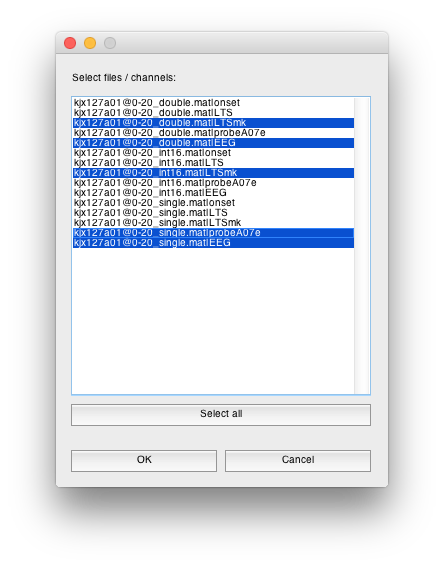

## `getstructNby1`

This method allows you to create a N by 1 colum of structure array each element of which represent a single channel and has fields that are common for all the channels. For the fields that exist only for a subset of channels, they are put in the `misc` field together. 

`list1 = chanSpec.getstructNby1;`

`list1 = chanSpec.getstructNby1();`

list1 = chanSpec.getstructNby1()

list1 = 15x1 struct array with fields:

    allindex
    matindex
    chanindex
    start
    comment
    interval
    samplingrate
    length
    chantype
    scale
    parentdir
    duration
    maxtime
    numofevents
    meanfiringrate
    offset
    parent
    title
    timeunit
    units


This method is powerful when you want to go through many channels across many .mat files to compare certain values in the Variable Editor in a spreadsheet-like look.

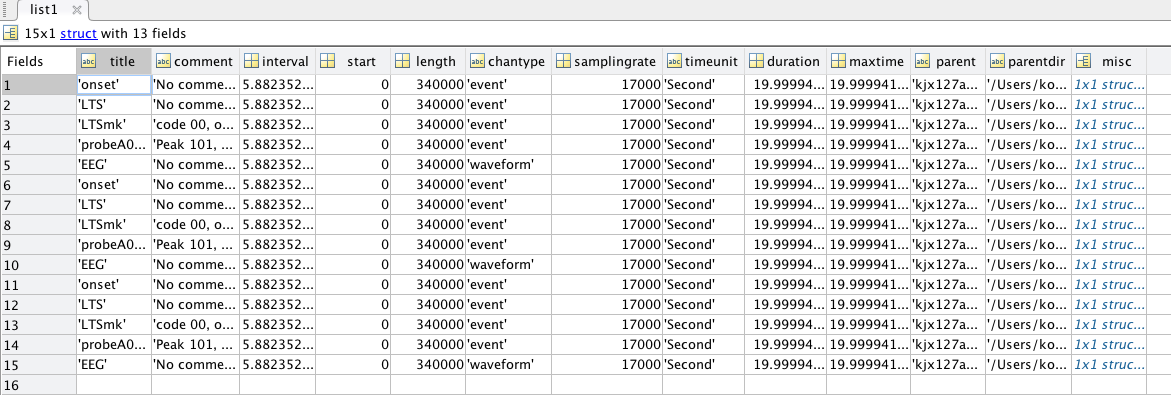

With an input argument `chanpropname` (string), you can subtract channels that have the specified channels that contain `chanpropname` as a field name.

`list2 = chanSpec.getstructNby1(chanpropname) `

In the example below, the filed 'scale' only exist for waveform data. So the output `list2` only contains waveform channels and thus it is a 3x1 structure array.

list2 = chanSpec.getstructNby1('scale') % exist only for some channels

list2 = 3x1 struct array with fields:

    allindex
    matindex
    chanindex
    title
    comment
    interval
    scale
    offset
    units
    start
    length
    chantype
    timeunit
    samplingrate
    duration
    maxtime
    parent
    parentdir


## `matnamesfull2matind`

`matind = matnamesfull2matind(chanSpec, matnamesfull)`

With matnamesfull specified, this method will rertun matind, indices for matfiles in cell columns.

matind = chanSpec.matnamesfull2matind(chanSpec.MatNamesFull(1:2))

matind =     [1]
    [2]


## `chantitles2chanind`

`chanind = chantitles2chanind(chanSpec, matnamesfull, chantitles)`

With matnamesfull and chantitles specified, this method will rertun chanind, indices for channels, and matind, indices of matfiles, in cell columns.

[chanind, matind] = chantitles2chanind(chanSpec, chanSpec.MatNamesFull([1,3]),...
    [{{'onset', 'EEG'}}, {{'onset', 'LTS'}}]);

chanind{:}

ans =      1
     5


ans =      1
     2


## `constructFileList`

FileList is a class that holds meta information about Record objects (RecordInfo objects). In effect, FileList class is similar to ChanSpecifier class in many ways. ChanSpecifier is designed to select specific subset of matfiles and channels from a list of .mat files, whereas FileList is useful to create Excel spreadsheet to store results of analyses (see saveSummaryXlsx).

`filelist = constructFileList(chanSpec, _____)`

is equivalent to the following

`filelist = FileList(chanSpec.MatNamesFull, _____);`

filelist = chanSpec.constructFileList('Name', 'newfilelist')

filelist =   FileList with properties:

        ListName: 'newfilelist'
            List: {3x1 cell}
         Comment: ''
    MemberTitles: {3x1 cell}


filelist.List

ans =     [1x1 RecordInfo]
    [1x1 RecordInfo]
    [1x1 RecordInfo]


## `constructRecord`

`rec = constructRecord(chanSpec, matindex)`

Constructs multiple Record onjects out of .mat files that are listed in chanSpec and specified by matindex.

The example below is to construct Record objects out of the first and third .mat files in `chanSpec.List`. The output is in cell array format in a cell of which a `Record` object is stored.

recs = chanSpec.constructRecord([1,3])

recs =     [1x1 Record]
    [1x1 Record]



recs{1}

ans =   Record with properties:

    RecordTitle: 'kjx127a01@0-20_double.mat'
          Chans: {5x1 cell}
           Time: [340000x1 double]
         Length: 340000
      SInterval: 5.8824e-05
        MaxTime: 19.9999
       Duration: 19.9999
     ChanTitles: {5x1 cell}
          Start: 0
          SRate: 17000


ans =     chantitles: {5x1 cell}
           fig: [1x1 Figure]
           axh: [5x1 Axes]
         lineh: {5x1 cell}


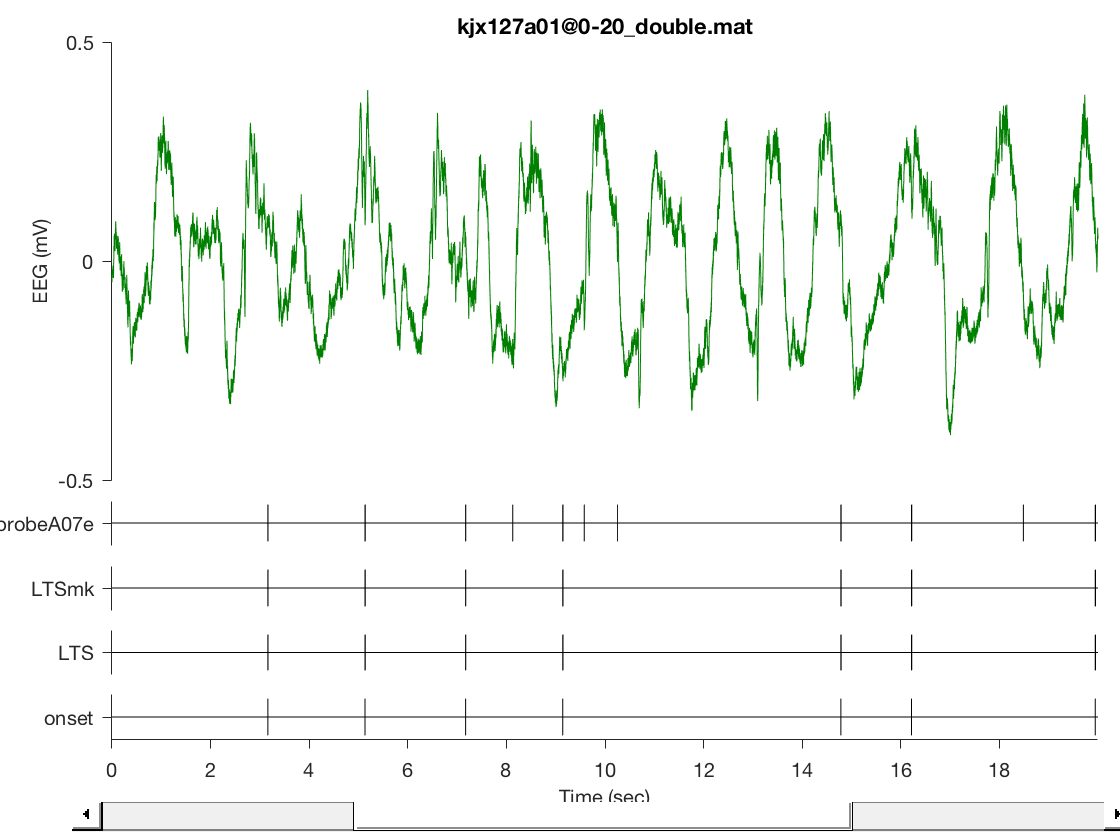


recs{1}.plot

`rec = constructRecord(chanSpec, matnamesfull)`

You can also specify .mat files by their full names. Here full names must be absolute paths.

fullpaths = chanSpec.MatNamesFull;
recs = chanSpec.constructRecord(fullpaths([1,3]));

recs{1}

ans =   Record with properties:

    RecordTitle: 'kjx127a01@0-20_double.mat'
          Chans: {5x1 cell}
           Time: [340000x1 double]
         Length: 340000
      SInterval: 5.8824e-05
        MaxTime: 19.9999
       Duration: 19.9999
     ChanTitles: {5x1 cell}
          Start: 0
          SRate: 17000


ans =     chantitles: {5x1 cell}
           fig: [1x1 Figure]
           axh: [5x1 Axes]
         lineh: {5x1 cell}


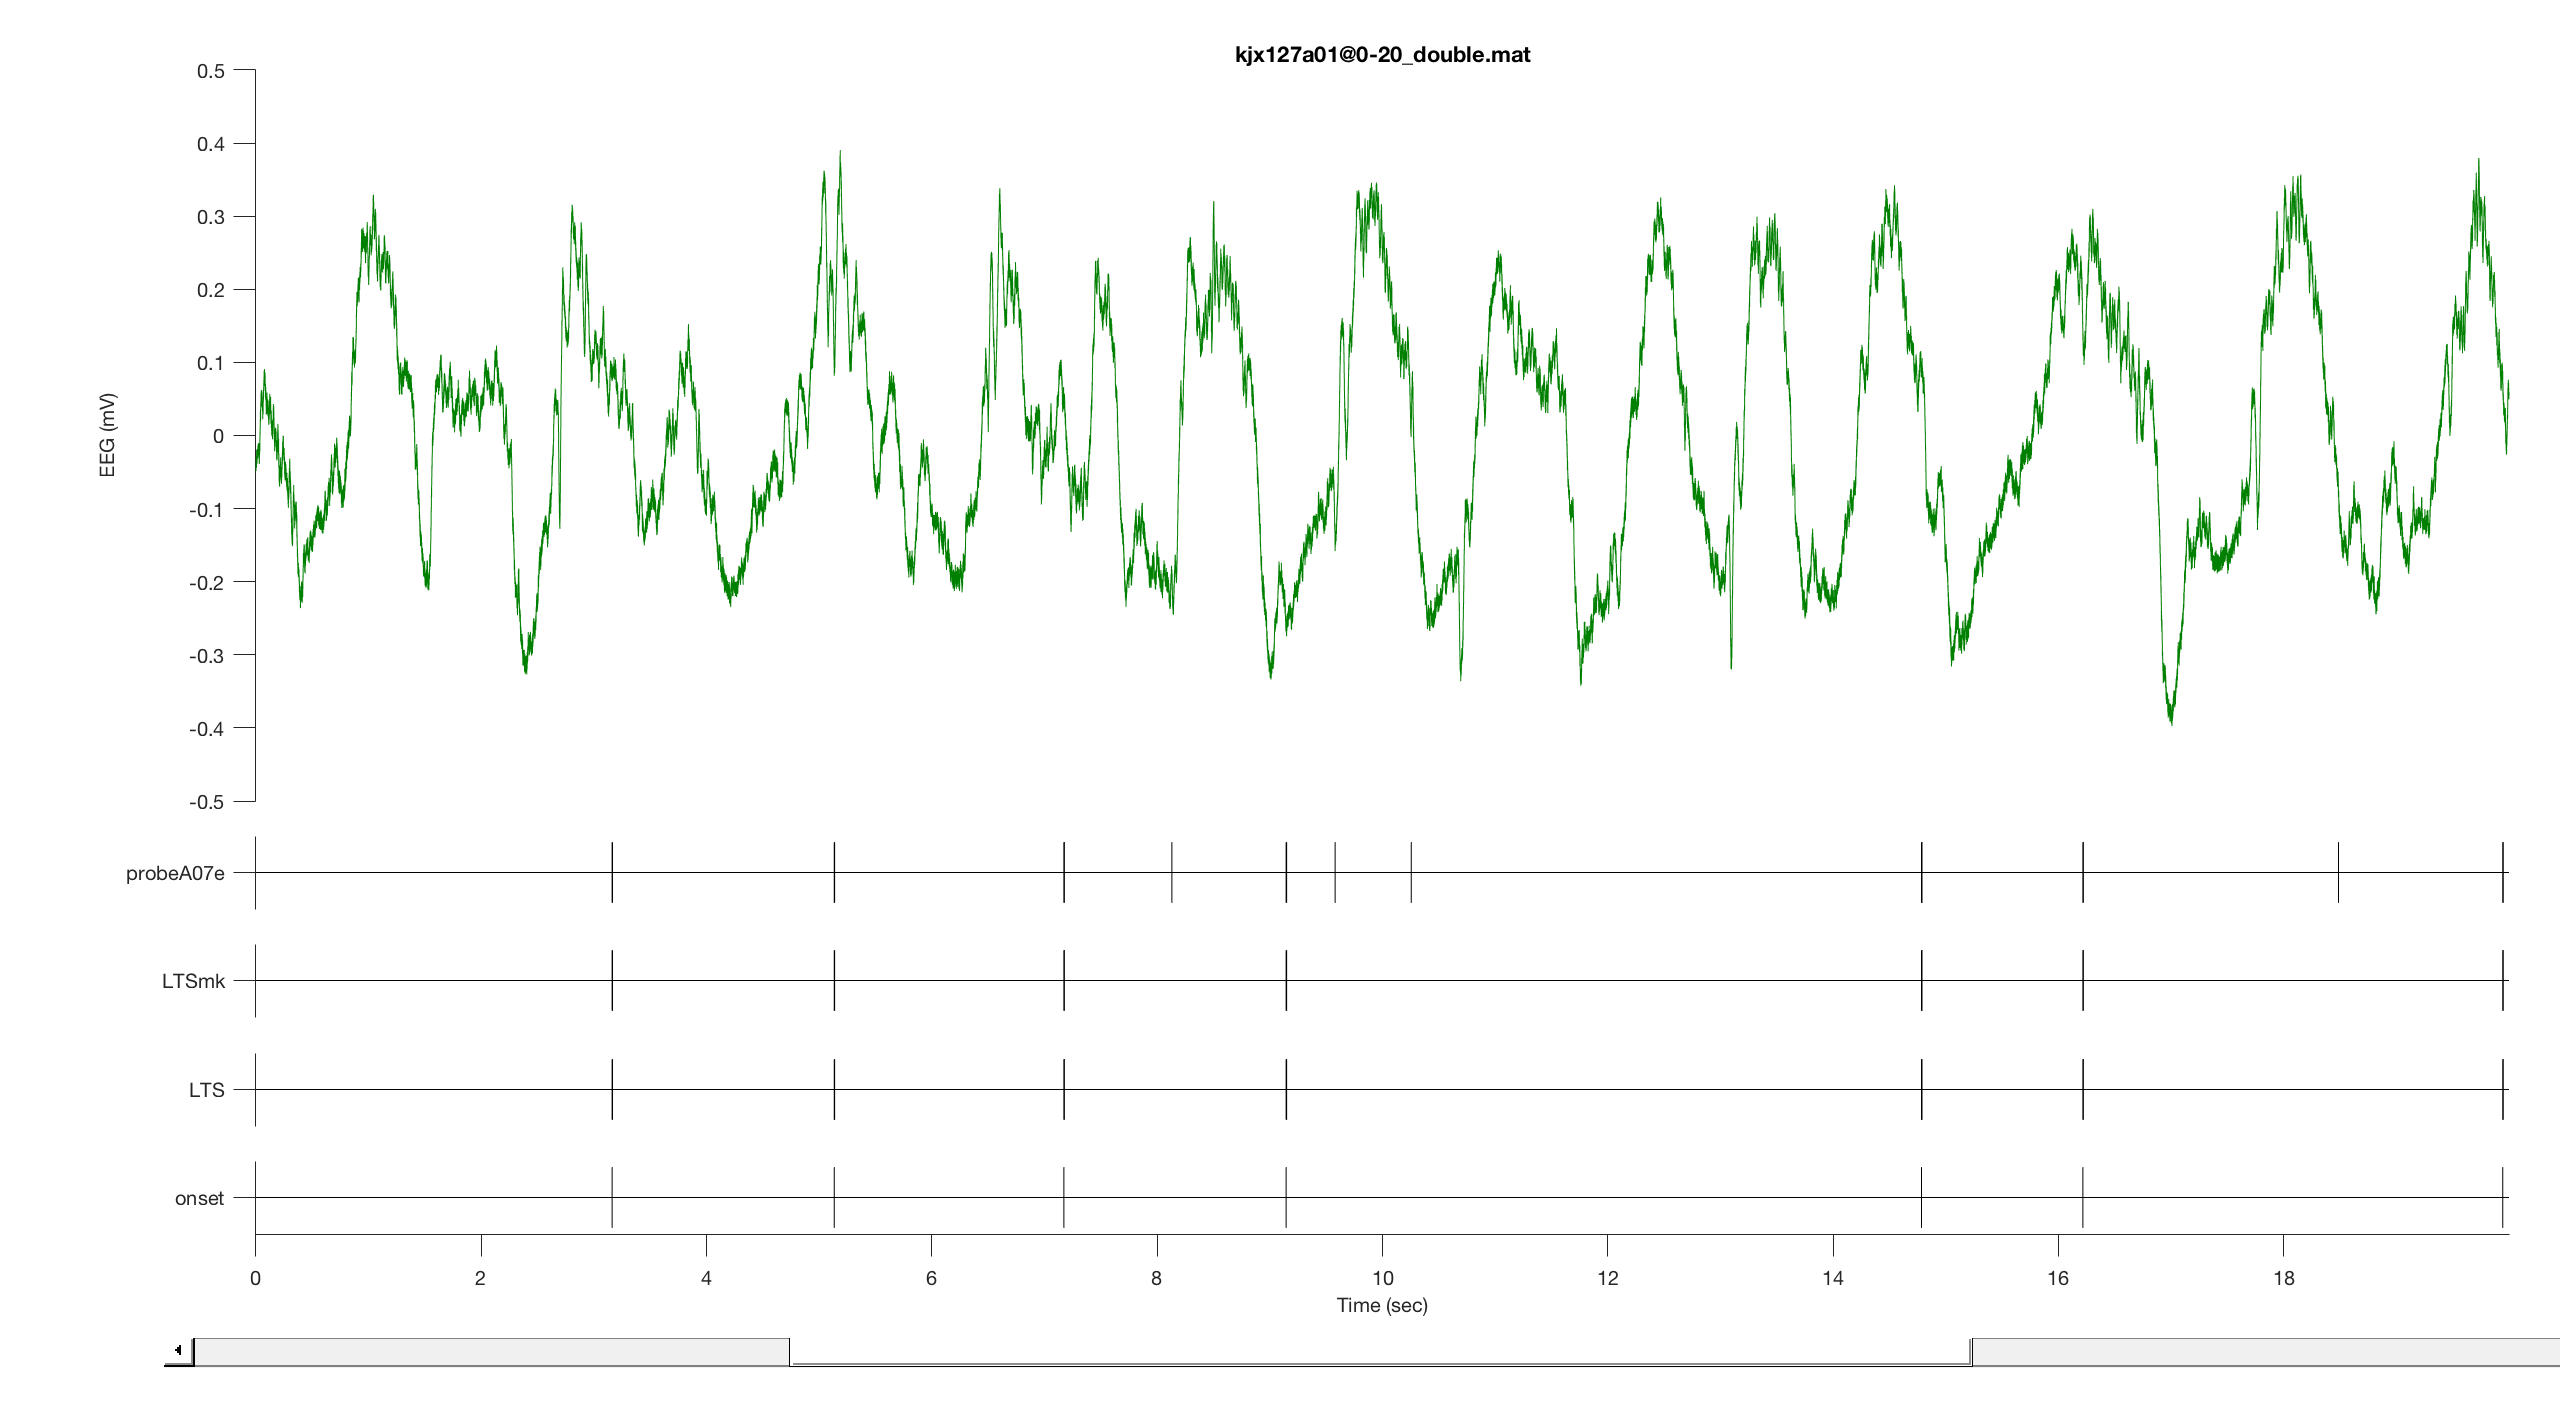


recs{1}.plot

Many methods are available for Record objects and their content WaveformChan objects and EventChan objects.

methods(Record)


Methods for class Record:

Record          
addchan         
eq              
extractTime     
getRecordInfo   
plot            
removechan      
resample        
subsasgn        
subsref         
summaryDataset  
testProperties  
vertcat         




methods(WaveformChan)


Methods for class WaveformChan:

WaveformChan               
chan2struct                
chan2ts                    
detectUPandDOWNwavelet     
eq                         
exportCSV                  
extractTime                
getBUA                     
getBUA2                    
getChanInfo                
max                        
mean                       
median                     
min                        
mode                       
neurospec_WavEve_sp2a_m1   
neurospec_WavWav_sp2a2_m1  
plot                       
plotCohere                 
plotPowerSpectrum          
plotSpectrogram            
plotTriggered              
plus                       
powerRatio                 
resample                   
setDataInt16               
std                        
sum                        
testProperties             
time                       
var                        
vertcat                    


Static methods:

constructChan              
doubleTOint16          

methods(EventChan)


Methods for class EventChan:

EventChan                 
chan2struct               
chan2ts                   
eq                        
extractTime               
getChanInfo               
getSpikeInfo              
max                       
mean                      
median                    
min                       
mode                      
neurospec_EveEve_sp2_m1   
neurospec_WavEve_sp2a_m1  
nextSpike                 
plot                      
plotCV2hist               
plotCV2vsISIpair          
plotCorr                  
plotISIbefaft             
plotISIhist               
plotInstantRate           
plotMeanFiringRate        
plotPSTH                  
plotPhaseHist             
plotRateHistogram         
plotTriggered             
plus                      
prevSpike                 
resample                  
std                       
sum                       
testProperties            
time                      
var                       
vertcat                 

## `eq`

You can use `eq` or `==` operator for chanSpec objects.

chanSpec == chanSpec % true

ans =      1



chanSpec2 = chanSpec;
chanSpec2.List(1).name = 'hoge';

chanSpec == chanSpec2 % false

ans =      0


## `vertcat`, `horzcat`

You can vertically concatenate chanSpec objects. Horizontal concatenaiton is equivalent to vertical concatenation.

chanSpec_cat = [chanSpec, chanSpec]

chanSpec_cat =   ChanSpecifier with properties:

                     List: [6x1 struct]
                 MatNames: {6x1 cell}
             MatNamesFull: {6x1 cell}
                ParentDir: {6x1 cell}
               ChanTitles: {6x1 cell}
            ChanTitlesAll: {30x1 cell}
    ChanTitlesMatNamesAll: {30x4 cell}
                   MatNum: 6
                  ChanNum: [6x1 double]



chanSpec_cat = [chanSpec; chanSpec]

chanSpec_cat =   ChanSpecifier with properties:

                     List: [6x1 struct]
                 MatNames: {6x1 cell}
             MatNamesFull: {6x1 cell}
                ParentDir: {6x1 cell}
               ChanTitles: {6x1 cell}
            ChanTitlesAll: {30x1 cell}
    ChanTitlesMatNamesAll: {30x4 cell}
                   MatNum: 6
                  ChanNum: [6x1 double]
